clear;

filename='C:\Users\Anuradha\Desktop\AUT_Venture_Demo\Test_Data\Data1\hr_radar_index.xlsx';
% m=1;
    

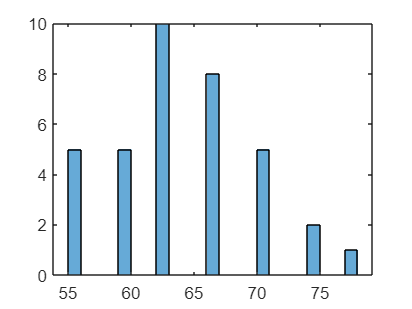

index_hr=readmatrix(filename);
    n=index_hr(1,7);
    index_hr_all=zeros(2,6);
    index_test=zeros(3,6);
   
    for i=1:95

        h=histogram(index_hr(i:i+5,1:6),'BinWidth',1);
        % observation duration
        x=h.BinEdges(h.BinCounts>0);
        y=h.BinCounts(h.BinCounts>0);
        x=x(x<=n+8);
        y=y(x<=n+8);
        x=x(x>=n-6);
        y=y(x>=n-6);
        index_test(2*i-1,1:length(x))=x;
        index_test(2*i,1:length(y))=y;
      
    end

    
    for i=1:95
        
       [~,freq_index_chk]=max(index_test(2*i,:));
       [~,freq_index]=min(abs(index_test(2*i-1,:)-n));
       if i==21
           [maxval,mafid]=mode(hr_ind_val(i-20:i-1,1));
       end
     
       if freq_index_chk<freq_index 
           if  i>20 && mafid>=12 
               [~,indx]=min(abs(index_test(2*i-1,1:6)-maxval));
               hr_ind_val(i,1)=index_test(2*i-1,indx);

           elseif (abs(index_test(2*i-1,freq_index_chk)-n)==3)&& (index_test(2*i-1,freq_index_chk)<60)
               hr_ind_val(i,1)=index_test(2*i-1,freq_index_chk)+4;

           else
               hr_ind_val(i,1)=index_test(2*i-1,freq_index_chk);
           end
       elseif (freq_index_chk>=freq_index) 
            
            if i>20 && mafid>=12
               [~,indx]=min(abs(index_test(2*i-1,1:6)-maxval));
               hr_ind_val(i,1)=index_test(2*i-1,indx);
            elseif length(nonzeros(index_test(2*i-1,:)))>freq_index_chk
                hr_ind_val(i,1)=round(mean(index_test(2*i-1,freq_index:freq_index+1)));
            else
                hr_ind_val(i,1)=index_test(2*i-1,freq_index_chk);
            end
       end

      
    end
    
      
   for i=96:100
       [~,indx]=min(abs(index_hr(i,1:6)-max(hr_ind_val(i-6:i-1,1))));
       hr_ind_val(i,1)=index_hr(i,indx);
   end
    

 
    
    

    

    [filepath,~,~] = fileparts(filename);
    f2 = fullfile(filepath,"rr_radar_index.xlsx");
    index_rr=readmatrix(f2);
    index_avg_rr=floor(mean(index_rr(:,1:3)));
    nr=index_rr(1,4);
    [~,idx]=min(abs(index_avg_rr-nr));
    rr_ind_val=index_rr(:,idx);
    for i= 1:100
        if abs(rr_ind_val(i,1)-nr)>=5
                rr_ind_val(i,1)=nr;
        end               
    end


        hr_radar=round(hr_ind_val.*(60*10/512));
        % for i=2:100
        %     if abs(hr_radar(i,1)-hr_radar(i-1,1))>=10
        %         hr_radar(i,1)=round(mean(hr_radar(i-1:i,1)));
        %     end
        % end

        hr_hex = round(index_hr(:, 8).*(60*10/512));
        hr_radar_avg=floor(mean(hr_radar))

hr_radar_avg = 69

        hr_hex_avg=floor(mean(hr_hex))

hr_hex_avg = 70

        % hr_compar(:,m)=hr_radar;
        % hr_compar(:,m+1)=hr_hex;
         rr_radar=round(rr_ind_val.*(60*10/512));
         rr_hex = round(index_rr(:, 5).*(60*10/512));
         rr_radar_avg=floor(mean(rr_radar))

rr_radar_avg = 13

         rr_hex_avg=floor(mean(rr_hex))

rr_hex_avg = 12

         % rr_compar(:,m)=rr_radar;
         % rr_compar(:,m+1)=rr_hex;
        % m=m+2;
        
